clear
addpath("geojsonR01\")

txt = readlines("N02-19_RailroadSection.geojson");
% txt = txt(4:end-3);
txt = strrep(txt,'鉄道区分','railsegments');
txt = strrep(txt,'事業者種別','companysegments');
txt = strrep(txt,'路線名','railname');
txt = strrep(txt,'運営会社','company');
geojson = jsondecode(strjoin(txt))

geojson = フィールドをもつ struct :
        type: 'FeatureCollection'
    features: [22016×1 struct]


%新幹線
figure;
gx = geoaxes;
hold(gx)

現在のプロットをホールドしました


railname = "山陽新幹線";
railcoordinate = parseCoordinate(geojson,railname);
geoplot(gx,railcoordinate(:,2),railcoordinate(:,1),'.',"Color","#0072BA")

railname = "東海道新幹線";
railcoordinate = parseCoordinate(geojson,railname);
geoplot(gx,railcoordinate(:,2),railcoordinate(:,1),'.',"Color","#FF7E1C")

railname = "東北新幹線";

railname = "東北新幹線"

railcoordinate = parseCoordinate(geojson,railname);
geoplot(gx,railcoordinate(:,2),railcoordinate(:,1),'.',"Color","#378640")

railname = "北海道新幹線";

railname = "北海道新幹線"

railcoordinate = parseCoordinate(geojson,railname);
geoplot(gx,railcoordinate(:,2),railcoordinate(:,1),'.',"Color","#03C13D")

railname = "九州新幹線";

railname = "九州新幹線"

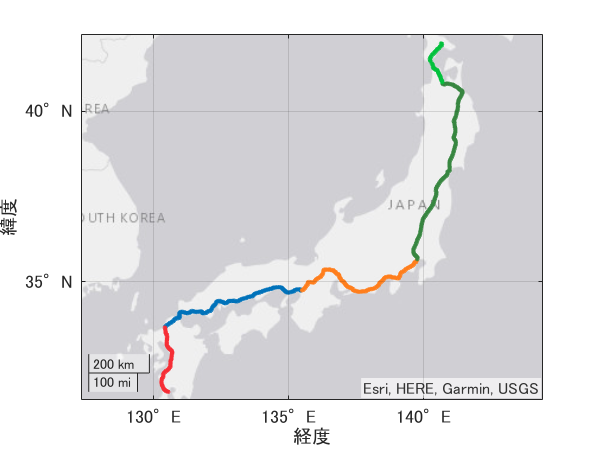

railcoordinate = parseCoordinate(geojson,railname);
geoplot(gx,railcoordinate(:,2),railcoordinate(:,1),'.',"Color","#F62E36")

hold off

%大阪
figure;
gx = geoaxes;
hold(gx)

現在のプロットをホールドしました


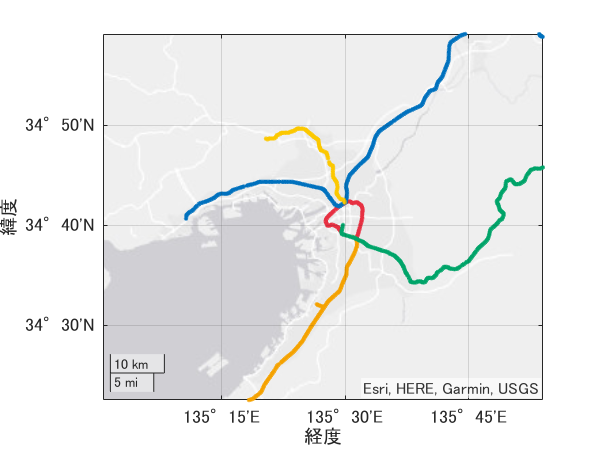

railname = "大阪環状線";
railcoordinate = parseCoordinate(geojson,railname);
geoplot(gx,railcoordinate(:,2),railcoordinate(:,1),'.',"Color","#e73042")

railname = "東海道線";
railcoordinate = parseCoordinate(geojson,railname);
geoplot(gx,railcoordinate(:,2),railcoordinate(:,1),'.',"Color","#0071be")

railname = "宝塚線";
railcoordinate = parseCoordinate(geojson,railname);
geoplot(gx,railcoordinate(:,2),railcoordinate(:,1),'.',"Color","#fcc800")

railname = "阪和線";
railcoordinate = parseCoordinate(geojson,railname);
geoplot(gx,railcoordinate(:,2),railcoordinate(:,1),'.',"Color","#f5a200")

railname = "関西線";
railcoordinate = parseCoordinate(geojson,railname);
geoplot(gx,railcoordinate(:,2),railcoordinate(:,1),'.',"Color","#00a469")

geolimits([34.39 34.97],[135.01 135.90])

%大阪地下鉄
figure;
gx = geoaxes;
hold(gx)

現在のプロットをホールドしました


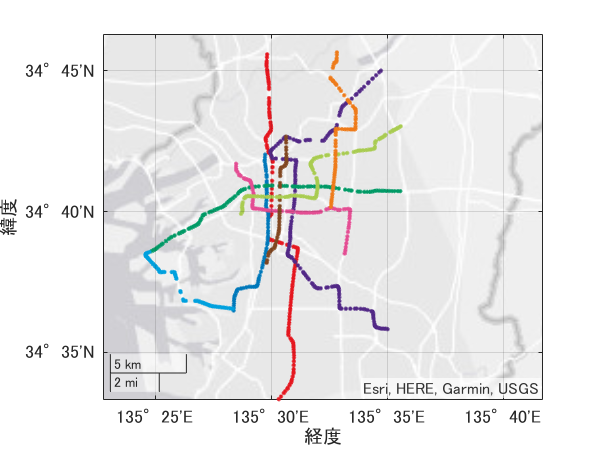


railname = "1号線(御堂筋線)";
railcoordinate = parseCoordinate(geojson,railname);
geoplot(gx,railcoordinate(:,2),railcoordinate(:,1),'.',"Color","#e5171f")

railname = "2号線(谷町線)";
railcoordinate = parseCoordinate(geojson,railname);
geoplot(gx,railcoordinate(:,2),railcoordinate(:,1),'.',"Color","#522886")

railname = "3号線(四つ橋線)";
railcoordinate = parseCoordinate(geojson,railname);
geoplot(gx,railcoordinate(:,2),railcoordinate(:,1),'.',"Color","#0078ba")

railname = "4号線(中央線)";
railcoordinate = parseCoordinate(geojson,railname);
geoplot(gx,railcoordinate(:,2),railcoordinate(:,1),'.',"Color","#019a66")

railname = "5号線(千日前線)";
railcoordinate = parseCoordinate(geojson,railname);
geoplot(gx,railcoordinate(:,2),railcoordinate(:,1),'.',"Color","#e44d93")

railname = "6号線(堺筋線)";
railcoordinate = parseCoordinate(geojson,railname);
geoplot(gx,railcoordinate(:,2),railcoordinate(:,1),'.',"Color","#814721")

railname = "7号線(長堀鶴見緑地線)";
railcoordinate = parseCoordinate(geojson,railname);
geoplot(gx,railcoordinate(:,2),railcoordinate(:,1),'.',"Color","#a9cc51")

railname = "8号線（今里筋線）";
railcoordinate = parseCoordinate(geojson,railname);
geoplot(gx,railcoordinate(:,2),railcoordinate(:,1),'.',"Color","#ee7b1a")

railname = "南港ポートタウン線";
railcoordinate = parseCoordinate(geojson,railname);
geoplot(gx,railcoordinate(:,2),railcoordinate(:,1),'.',"Color","#00a0de")

geolimits([34.541 34.785],[135.348 135.724])

function [railcoordinate] = parseCoordinate(geojson,railname)
    railcoordinate = [];
        for ii=1:length(geojson.features)
        if string(geojson.features(ii).properties.railname)==railname
            railcoordinate = [railcoordinate;geojson.features(ii).geometry.coordinates];
        end
        end
        railcoordinate = sortrows(railcoordinate);
end